# Get Started with Solver-Based Optimize Live Editor Task

This example script helps you to use the solver-based **Optimize** Live Editor task for optimization or equation solving. Modify the script for your own problem.

The script solves a nonlinear optimization problem with nonlinear constraints.

## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

Set the initial point `x0` and scale `a` for the optimization.

x0 = 2*pi*rand(1,10);

**Place the **`x0`** value and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

Usually, you place the Optimize Live Editor task into the script by selecting **Task > Optimize** in the **Live Editor** tab, or by selecting **Task > Optimize** in the **Insert** tab. Then you are presented with the following choice (this is only a picture, not the real task):

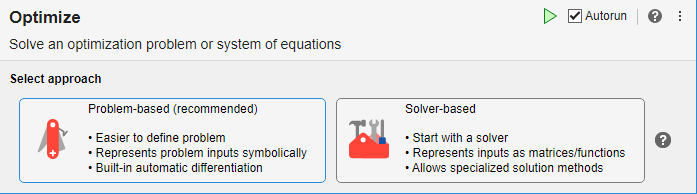

To get the solver-based task, click **Solver-based**.

The following solver-based task has objective and nonlinear constraint functions included. To change these functions, edit the function listings below the task.

To change the constraints, select appropriate constraint types and enter values in the input boxes. You might need to enter values in the section containing `x0` above, and run the section to put values in the workspace.

Run the task by clicking the striped bar to the left, or by choosing **Run** or **Section > Run Section**, or by pressing `Control+Enter`.

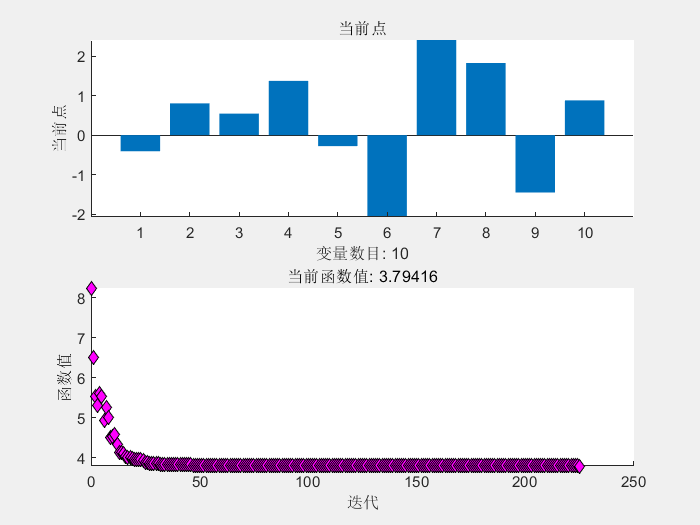


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



% 设置非默认求解器选项
options = optimoptions("fmincon","PlotFcn",["optimplotx","optimplotfval"]);

% 求解
[solution2,objectiveValue2] = fmincon(@objectiveFcn,x0,[],[],[],[],...
    repmat(-3.14,size(x0)),repmat(3.14,size(x0)),[],options);


% 清除变量
clearvars options

## Results

`Optimize` saves the solution to the workspace variable `solution`, and saves the objective function value at the solution to the workspace variable `objectiveValue`. You can see and modify these variable names at the top of the `Optimize` task.

View these variables.

solution2

solution2 =    -0.4062    0.8039    0.5456    1.3712   -0.2754   -2.0666    2.4045    1.8230   -1.4487    0.8788


objectiveValue2

函数或变量 'objectiveValue' 无法识别。

View the nonlinear constraint function values at the solution.

[ccons,ceqcons] = constraintFcn(solution)

%%PLT
t=linspace(0,2,2000);
sum_=zeros;
for i=1:10
    sum_=sum_+sin(2*pi*(69+i)*t+solution2(i));
end
PAR=10*log10((max(sum_)).^2/10);
disp(append("PAR=",num2str(PAR),"dB"));

PAR=1.7799dB


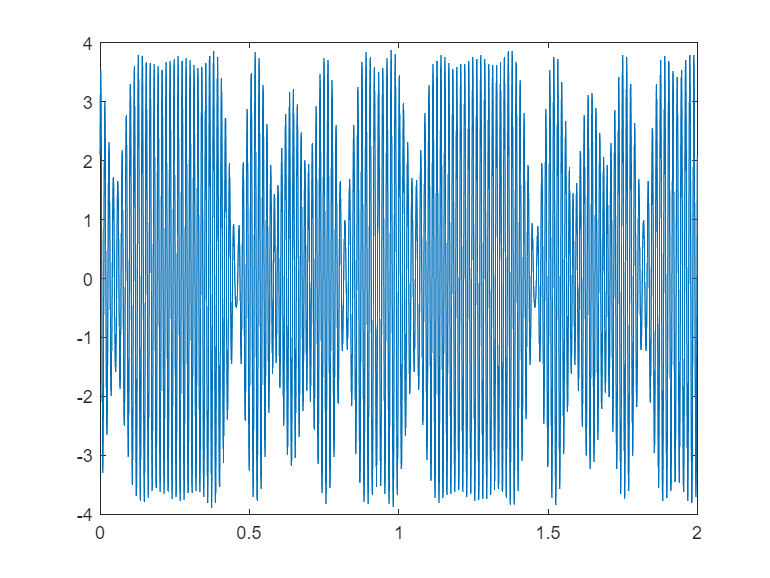

figure
plot(t,sum_)

## Helper Functions — Local Functions

The following code creates the objective function. Modify this code for your problem.

function f = objectiveFcn(x)
t=linspace(0,2,1000);
f = max(sin(2*pi*70*t+x(1))+sin(2*pi*71*t+x(2))+sin(2*pi*72*t+x(3))+sin(2*pi*73*t+x(4))+sin(2*pi*74*t+x(5))+sin(2*pi*75*t+x(6))+sin(2*pi*76*t+x(7))+sin(2*pi*77*t+x(8))+sin(2*pi*78*t+x(9))+sin(2*pi*79*t+x(10)));
end

The following code creates the constraint function. Modify this code for your problem.

function [c,ceq] = constraintFcn(x)
%c(1) = x(1)^2 + x(2)^2 - 5;
%c(2) = 3 - x(1)^2 - x(2)^2;
%ceq = [];  % No equality constraints
end

*Copyright 2020 The MathWorks, Inc.*